## Multiplikative Modultion (Cosinus): B-PSK Signal

% Alles löschen und aufräumen
close all; clear all; clc;
% Zusätzlich Pfad vom ersten Übungsblatt angeben -> Für plotfft
addpath('../../../60_Labor/01_Uebungsblatt_Musterloesung/');   
addpath('../../../60_Labor/02_Uebungsblatt_Musterloesung/');   

### Anlegen der Signale

% Festlegung der Parameter
fa = 50e3; Ta = 1 / fa;
fs = 1000; Ts = 1 / fs;
fc = 8000;

% Erstellen von zufälligen Bits
Nbits = 50;
bits = round(rand(1, Nbits), 0);

% Berechnung der Signallänge für reeller harmonische Schwingung
Nsym = Nbits;
N_samples = floor(Nsym * (Ts / Ta)); 
Tb = Ta * N_samples - Ta;

% Erzeugung der Signale
ybpsk = PskGen(bits, fs, fa, 'BPSK');
ycos_b = SigGen(Tb, fa, 'cos', fc);

### Darstellung des Basisband-Signals

disp('B-PSK Signal im Basisband');

B-PSK Signal im Basisband


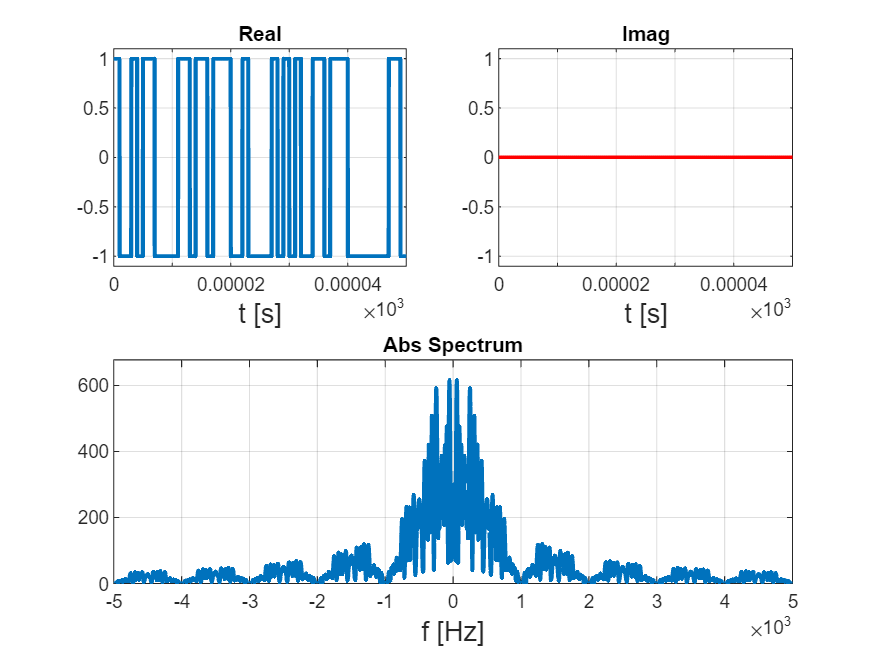

plotfft(ybpsk, fa, 'DisplaySignal', 'both', 'Nfft', 10240, 's', 1, 'Title', "B-PSK-Signal im Basisband");
xlim([-5000, 5000]);

### Modulation des Signals

% Multiplikation der Signale
ybpsk_bp = ybpsk .* ycos_b;

### Darstellung des Bandpass-Signals

disp('B-PSK Signal im Bandpass');

B-PSK Signal im Bandpass


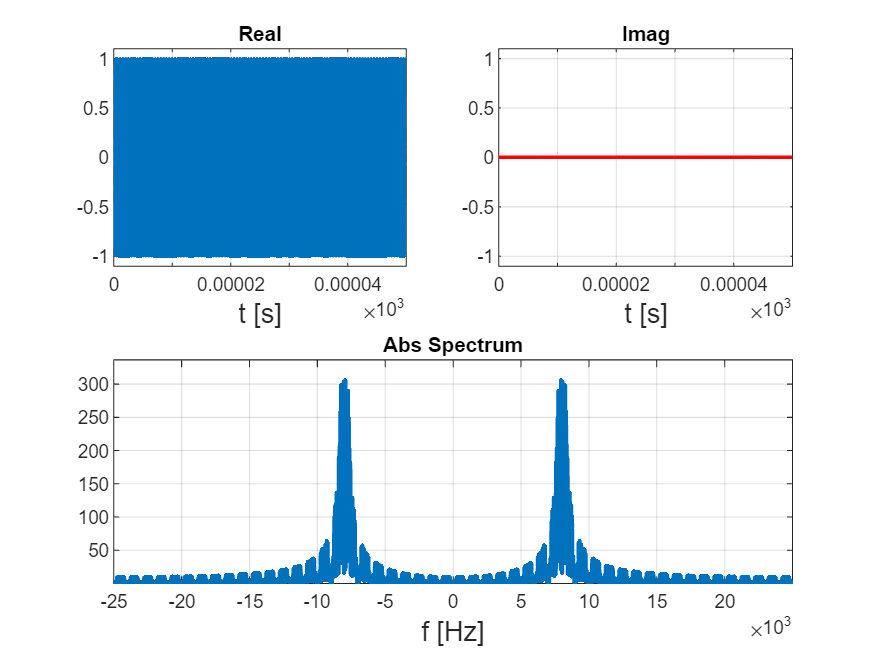

plotfft(ybpsk_bp, fa, 'DisplaySignal', 'both', 'Nfft', 10240, 's', 1, 'Title', "B-PSK-Signal im Bandpass");

### Demodulation des Signals

% Multiplikation der Signale
ybpsk_bb = ybpsk_bp .* ycos_b;

### Darstellung des Demodulierten Basisband-Signals

disp('B-PSK Signal im Basisband (Nach Demodulation)');

B-PSK Signal im Basisband (Nach Demodulation)


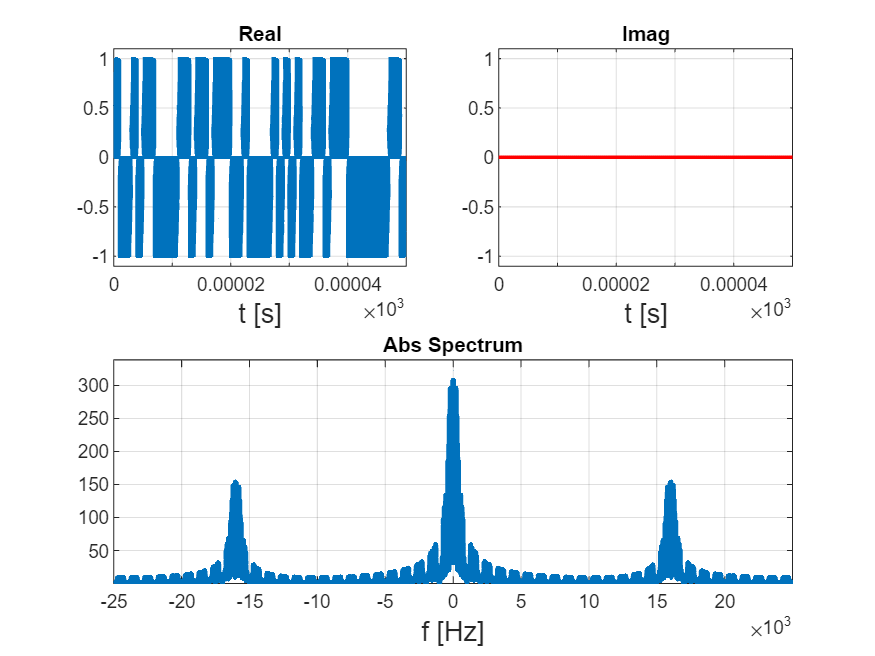

plotfft(ybpsk_bb, fa, 'DisplaySignal', 'both', 'Nfft', 10240, 's', 1, 'Title', "B-PSK-Signal im Basisband (Nach Demodulation)");

### Anwendung des Tiefpasses

% Fir Filter Erstellen
firFilterObj = genFirFilter();
fir_coef = firFilterObj.Numerator;
fir_coef = fir_coef / sum(fir_coef);

% Fir Filter Anwenden
ybpsk_bb_fir = conv(ybpsk_bb, fir_coef);

% Ein- und Auschwingvorgänge entfernen
N_fir_half = floor (length(fir_coef) / 2);
ybpsk_bb_fir = ybpsk_bb_fir( N_fir_half : length(ybpsk_bb_fir) - N_fir_half);

### Darstellung des Demodulierten Tiefpass-Gefilterten Basisband-Signals

disp('B-PSK Signal im Bandpass (Nach Demodulation und nach Tiefpass)');

B-PSK Signal im Bandpass (Nach Demodulation und nach Tiefpass)


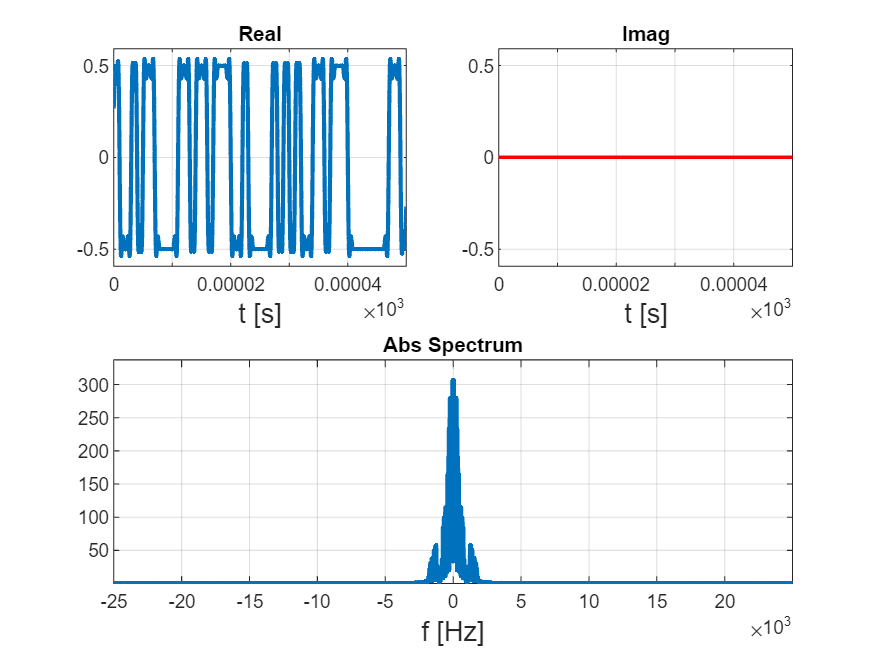

plotfft(ybpsk_bb_fir, fa, 'DisplaySignal', 'both', 'Nfft', 10240, 's', 1, 'Title', "B-PSK-Signal im Basisband (Nach Demodulation und nach Tiefpass)");